% Create path
clear all; close all; clc
addpath(genpath(cd)); % add all subfolders of cd to path

This live script runs auto_ultrasound.m, resulting in an estimation of muscle fascicle length and pennation angle. In this live script, parameters can be adjusted and their effect can be investigated. 

Tim van der Zee 2021-01-04, tim.vanderzee@ucalgary.ca

## Load and plot image, specify aponeurosis region

load('parms.mat'); % start with default parameters
load('Data\example_ultrasound_image.mat')
[n,m] = size(data); % data needs to be a n-by-m numeric array

figure(1); imshow(data); title('raw image')

% Aponeurosis cutting: fraction of vertical (0-1)
parms.apo.supercut(1) = 0.01; % superficial boundary superficial aponeurosis
parms.apo.supercut(2) = 0.12; % deep boundary superficial aponeurosis
parms.apo.deepcut(1) = 0.58; % superficial boundary deep aponeurosis
parms.apo.deepcut(2) = 0.92; % deep boundary deep aponeurosis

color = get(gca,'colororder')

color =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840


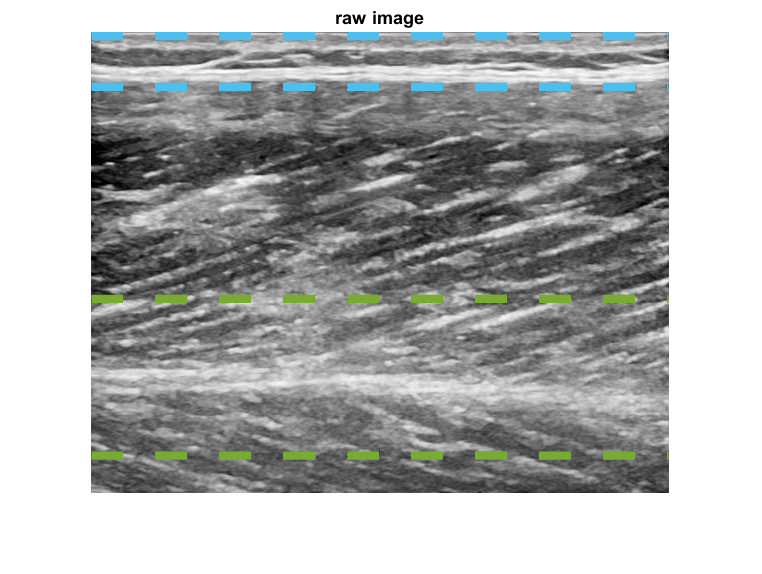

for i = 1:2
    line('xdata', [1 m] , 'ydata', n.*[parms.apo.supercut(i) parms.apo.supercut(i)],...
        'linewidth',5, 'linestyle', '--', 'color', color(6,:))
    line('xdata', [1 m] , 'ydata', n.*[parms.apo.deepcut(i) parms.apo.deepcut(i)],...
        'linewidth',5, 'linestyle', '--', 'color', color(5,:))
end


% saveas(gcf,'example3.png')

## Frangi filtering

As described in the documentation of FrangiFilter2D, the function uses the eigenvectors of the Hessian to compute the likeliness of an image region to vessels, according to the method described by Frangi, 2001 (Chapter 2). Thinner lines can be detected by using small values for the range (fascicles), and thicker lines can be detected by using large values for the range (aponeuroses)

% aponeurosis filtering
parms.apo.frangi.FrangiScaleRange(1) = 18; % lower limit on thickness range (pixels)
parms.apo.frangi.FrangiScaleRange(2) = 20; % upper limit on thickness range (pixels)

% fascicle filtering
parms.fas.frangi.FrangiScaleRange(1) = 1; % lower limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRange(2) = 2; % upper limit on thickness range (pixels)

% do filtering
aponeurosis = FrangiFilter2D(double(data), parms.apo.frangi);

Current Frangi Filter Sigma: 18
Current Frangi Filter Sigma: 19
Current Frangi Filter Sigma: 20


fascicle = FrangiFilter2D(double(data), parms.fas.frangi);

Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2


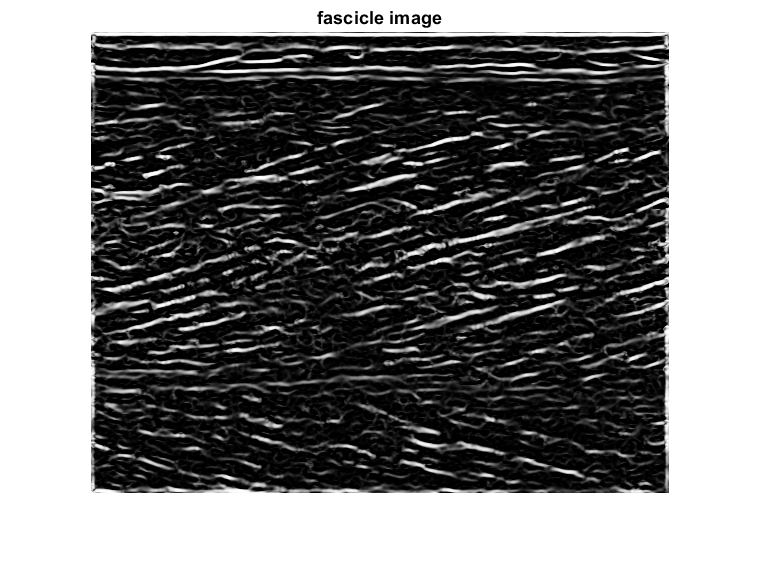


figure; imshow(fascicle); title('fascicle image')

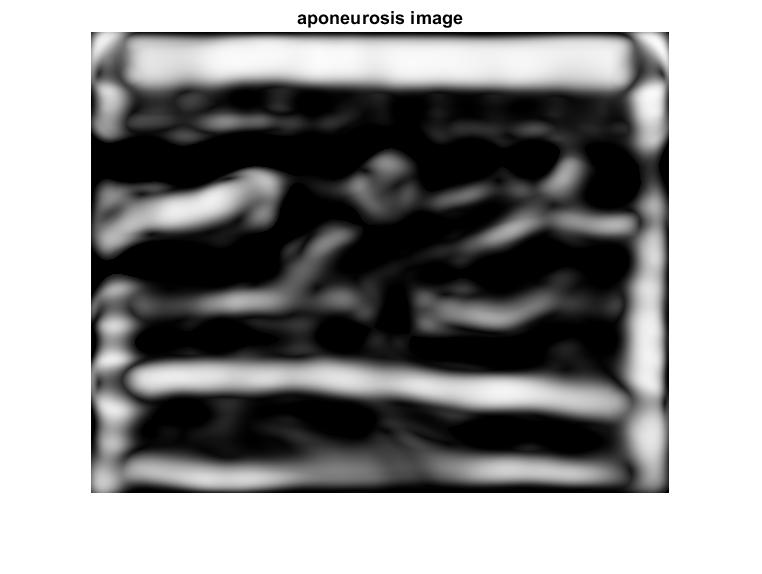

figure; imshow(aponeurosis); title('aponeurosis image')

## Specify parameters and determine alpha, betha, thickness

Current Frangi Filter Sigma: 18
Current Frangi Filter Sigma: 19
Current Frangi Filter Sigma: 20
Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2


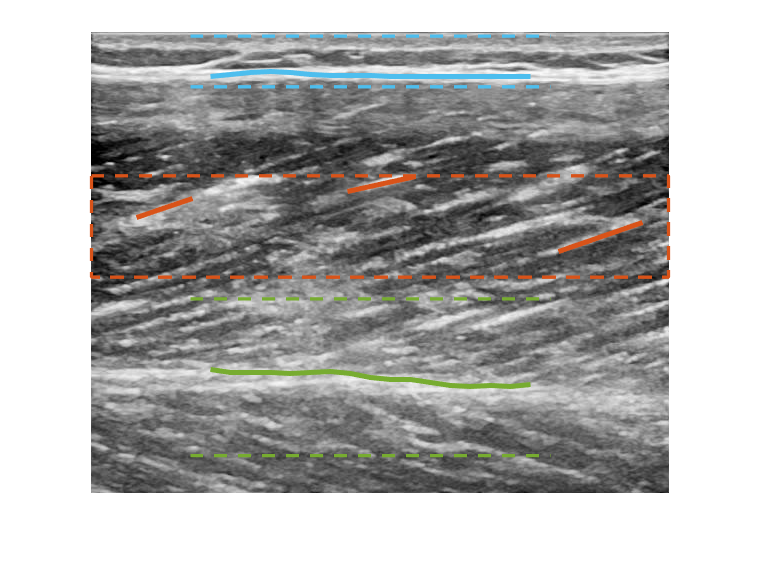

% Aponeurosis selection criteria
parms.apo.superrange(1) = -10; % smallest superficial aponeurosis angle considered (deg)
parms.apo.superrange(2) = 30; % largest superficial aponeurosis considered (deg)
parms.apo.deeprange(1) = -20; % smallest deep aponeurosis angle considered (deg)
parms.apo.deeprange(2) = 10; % largest deep aponeurosis considered (deg)
parms.apo.minlength = 200; % minimal length for aponeurosis object (pixels) 
parms.apo.maxlengthratio = 0.8; % maximal ratio between longest and second longest object
parms.apo.fillgap = 5; % gap filling in the aponeurosis (pixels)

% Define the horizontal aponeurosis spacing
apomargin = 100; % distance between start aponeurosis objects and the sides (pixels)
apospacing = 20; % horizontal spacing for aponeurosis (pixels) 
parms.apo.apox = apomargin:apospacing:(m-apomargin);

% Fascicle cutting
parms.fas.cut = 0.11; % relative amount kept from the middle

% Hough parameters arameters
parms.fas.range(1) = 10; % smallest fascicle angle considered (deg)
parms.fas.range(2) = 30; % largest fascicle angle considered (deg)
parms.fas.npeaks = 5; % amount of Hough angles included in weighted average

% Show figure?
parms.show = true;

% Run auto_ultrasound
[alpha, betha, thickness] = auto_ultrasound(data,parms);


% Display things
disp(['Fascicle angle = ' , num2str(round(alpha,3)), ' deg' ])

Fascicle angle = 18.406 deg


disp(['Superficial aponeurosis angle = ' , num2str(round(betha,3)), ' deg' ])

Superficial aponeurosis angle = -0.29 deg


disp(['Muscle thickness = ' , num2str(round(thickness,3)), ' pixels' ])

Muscle thickness = 302.643 pixels


## Fascicle length and pennation angle calculation

Based on geometry, pennation angle (phi) equals the difference between fascicle angle (alpha) and superficial aponeurosis angle (betha). Fascicle length (faslen) equals the ratio between muscle thickness and pennation angle. See Fig. 1 in *van der Zee & Kuo (2020a):* [https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1](https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1)

% Pennation angle (phi) and fascicle length
phi = alpha - betha;
faslen = thickness ./ sind(phi);

% Display pennation angle and fascicle length
disp(['Pennation angle = ' , num2str(round(phi,2)), ' deg' ])

Pennation angle = 18.7 deg


disp(['Fascicle length = ' , num2str(round(faslen,1)), ' pixels'])

Fascicle length = 944.2 pixels



if exist('pixtocm','var')
    faslen_cm = faslen / pixtocm;
    disp(['Fascicle length = ' , num2str(round(faslen_cm,2)), ' cm'])
end

Fascicle length = 8.19 cm


## Application: energetic cost of cyclic muscle force production

Fascicle lengths and pennation angles may be used to estimate muscle moment arms and the amount of mechanical work done by the muscle. See *van der Zee & Kuo (2020b):* [https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1](https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1)